## Load Necessary Saved Data

clear; clc; close all;
loadData = load("C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\ASML_EC_Sim_Run_twoShot_13_Jan_2023_13_57_15.mat");
logsout = loadData.logsout;
ec = loadData.ec;
clear loadData;

**WARNING: Much of the provided data will have ECdriveLaserGainCommand < 1. You **

**should only extract OL EUV data where ECdriveLaserGainCommand == 1, unless you have a special need for that lower energy data, e.g., ID of the transfer function from gain command to EUV.**

Ts = 20e-6; % nominal 50kHz sample rate
% generate a time vector equal to the length of the data vector
t = Ts*(1:length(ec.ECeuvValue))'-Ts;
% set the open-loop EUV and enab signal as inputs:
enab = ec.ECeuvValue > 1; % not terribly robust; exercise for the reader

## Plot the simulated closed-loop EUV side-by-side with the open-loop EUV

There's an error buried somewhere, which is causing some zero-EUV values to slip through. You will want to fix it at some point.

figure;
idx = logical(logsout.enab); % only want to show values where EUV is positive
h(1) = subplot(1,2,1);
binscatter(logsout.T_Eol(idx),logsout.Eol(idx),100)
yulim = max(ylim); % for linking the y-axes
colormap('jet') % add some pretty colors
hold on;
title('EUV Open Loop');
target = logsout.target;
target_array = target * ones(size(logsout.T_Ecl));

plot(logsout.T_Ecl(idx),target_array(idx),'LineWidth',2,'Color',"white");

h(2) = subplot(1,2,2);
binscatter(logsout.T_Ecl(idx),logsout.Ecl(idx),100); hold on;
xlabel('Time [s]')
target = logsout.target;
target_array = logsout.target * ones(size(logsout.T_Ecl));

plot(logsout.T_Ecl(idx),target_array(idx),'LineWidth',2,'Color',"white");

ylim([min(ylim),yulim])
colormap('jet')
linkaxes(h,'y');
title('EUV Closed Loop');
xlabel('Time [s]')

## Calculate dose error for one burst

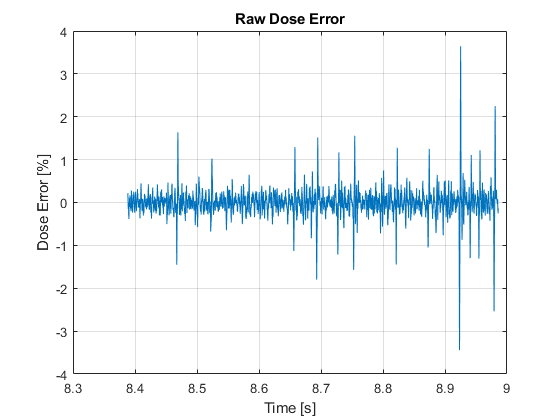

clear idb DE 
% load slit
load Slit.mat %F vector is trapezoid filter

% index the bursts
burstIndex = cumsum([0;diff(logsout.enab(:))>0.5]);

% pick out the first burst as an example
CHOSEN_BURSTINDEX = 11;
idb = (burstIndex == CHOSEN_BURSTINDEX)&logsout.enab;

% calculate dose error and plot as percentage
% DE is calculated for a single burst only specified by idb
DE = computeDose1Burst(logsout.T_Ecl(idb),logsout.Ecl(idb),logsout.target,F);

figure;
plot(logsout.T_Ecl(idb),DE*100); grid on;
xlabel('Time [s]'); ylabel('Dose Error [%]');
title('Raw Dose Error')

## Dose Data Filtering

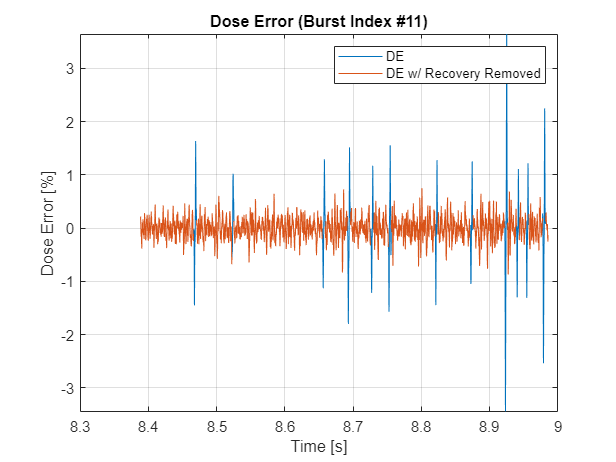

DEkilled = computeDose1Burst_filtered(logsout.T_Ecl(idb),logsout.Ecl(idb),logsout.target,F);

dose_time = logsout.T_Ecl(idb);

figure;
plot(dose_time,100*DE); hold on; grid on;
plot(dose_time,100*DEkilled)
xlabel("Time [s]")
ylabel("Dose Error [%]")
title(['Dose Error (Burst Index #' num2str(CHOSEN_BURSTINDEX) ')']);
ylim([min(DE*100) max(DE*100)]);
legend('DE','DE w/ Recovery Removed');

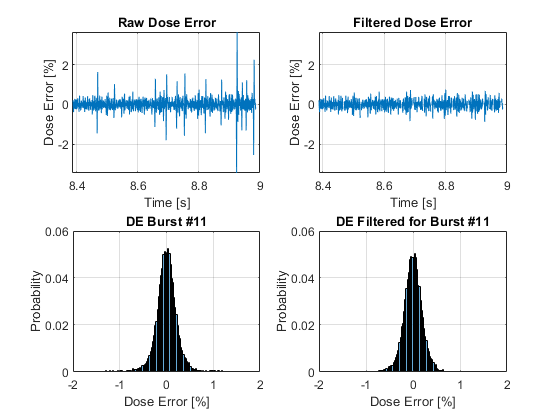

figure;
subplot(2,2,1)
plot(dose_time,100*DE)
xlabel("Time [s]")
ylabel("Dose Error [%]")
title('Raw Dose Error')
ylim([min(DE*100) max(DE*100)]); grid on;
subplot(2,2,2)
plot(dose_time,100*DEkilled)
xlabel("Time [s]")
ylabel("Dose Error [%]")
title('Filtered Dose Error');
ylim([min(DE*100) max(DE*100)]); grid on;

binwidth = 0.025;
subplot(2,2,3);
histogram(DE*100,'Normalization','probability','BinWidth',binwidth)
title(['DE Burst #', num2str(CHOSEN_BURSTINDEX)]);
xlim([-2 2]); grid on;
xlabel('Dose Error [%]'); ylabel('Probability');

subplot(2,2,4);
histogram(DEkilled*100,'Normalization','probability','BinWidth',binwidth)
xlim([-2 2]);
title(['DE Filtered for Burst #', num2str(CHOSEN_BURSTINDEX)]);
xlabel('Dose Error [%]'); ylabel('Probability'); grid on;

## TOTAL DATASET DOSE ERROR STATISTICS

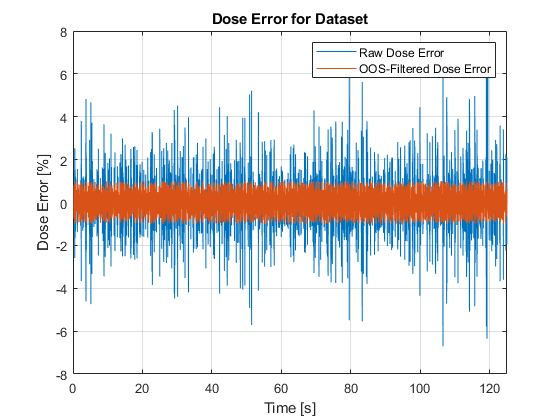

clear DE
logsout.enab = logical(logsout.enab); % grrrrr
GB = findgroups(burstIndex(logsout.enab));

temp = splitapply(@(t,e){computeDose1Burst(t,e,logsout.target,F)},...
  logsout.T_Ecl(logsout.enab), ...
  logsout.Ecl(logsout.enab), ...
  GB);
DE = nan(size(logsout.enab));
DE(logsout.enab) = vertcat(temp{:});

DE_filtered = remove_OOS(DE);
OOS_idx = getOOSlocations(DE);

figure;
plot(logsout.T_Ecl,100*DE)%,'.')
hold on; grid on;
plot(logsout.T_Ecl,100*DE_filtered);
xlabel("Time [s]")
ylabel("Dose Error [%]")
title('Dose Error for Dataset');
legend('Raw Dose Error','OOS-Filtered Dose Error');
xlim([0 max(logsout.T_Ecl)])

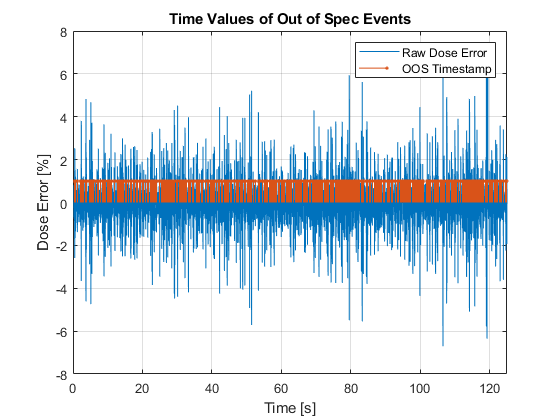

figure; clf;
plot(logsout.T_Ecl,100*DE); hold on;
stem(logsout.T_Ecl(OOS_idx == 1),OOS_idx(OOS_idx == 1),'.');
title('Time Values of Out of Spec Events'); grid on;
xlabel('Time [s]'); ylabel('Dose Error [%]');
legend('Raw Dose Error','OOS Timestamp'); xlim([0 max(logsout.T_Ecl)])

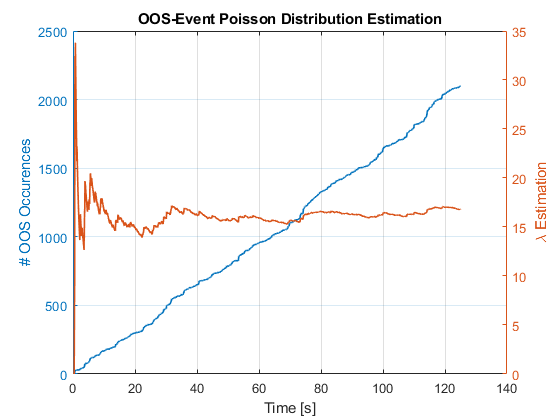

%change to negative OOS event

figure; clf;
yyaxis left
numOOS = cumsum(OOS_idx);
plot(logsout.T_Ecl,numOOS,'LineWidth',1.25); grid on;
title('OOS-Event Poisson Distribution Estimation')
xlabel('Time [s]'); ylabel('# OOS Occurences');
yyaxis right
lambda = movmean(numOOS./logsout.T_Ecl,1);
plot(logsout.T_Ecl,lambda,'LineWidth',1.25);
ylabel('\lambda Estimation')

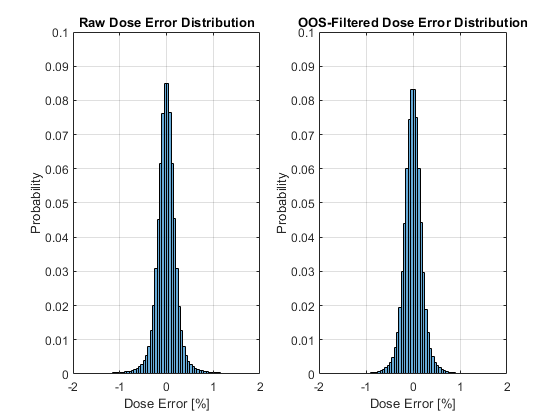


figure;
binwidth = 0.05;
subplot(1,2,1);
histogram(DE*100,'Normalization','probability','BinWidth',binwidth)
title('Raw Dose Error Distribution');
xlim([-2 2]); grid on; xlabel('Dose Error [%]'); ylabel('Probability');
ylim([0 0.1]);

subplot(1,2,2);
histogram(DE_filtered*100,'Normalization','probability','BinWidth',binwidth)
title('OOS-Filtered Dose Error Distribution');
xlim([-2 2]); xlabel('Dose Error [%]'); ylabel('Probability'); grid on;
ylim([0 0.1]);

DEmean = nanmean(DE); DEstd = nanstd(DE);
DEfiltmean = nanmean(DE_filtered); DEfiltstd = nanstd(DE_filtered);
disp('######### DOSE ERROR METRICS #########');

######### DOSE ERROR METRICS #########


%disp(['Raw Dose Error Mean = ', num2str(DEmean*100)]);
disp(['Raw Dose Error Std = ', num2str(DEstd*100)]);

Raw Dose Error Std = 0.29155


%disp(['OOS-Filtered Dose Error Mean = ', num2str(DEfiltmean*100)]);
disp(['OOS-Filtered Dose Error Std = ', num2str(DEfiltstd*100)]);

OOS-Filtered Dose Error Std = 0.1964


disp(['Number of OOS-Events = ', num2str(max(numOOS))]);

Number of OOS-Events = 2100


## Exercises for the reader

Modify the simulation to run with different sensor delays.

How can we model the distribution of the die yield (for example, to determine confidence intervals)?

- Try a Poisson process. 

- Is the estimate good? Why or why not?

How would you compute the spectrum of EUV and/or dose?

- Consider the relationship between the spectrum of EUV, the frequency response of the controller, the frequency response of the slit filter, and the spectrum of dose.

## Spectral Analysis

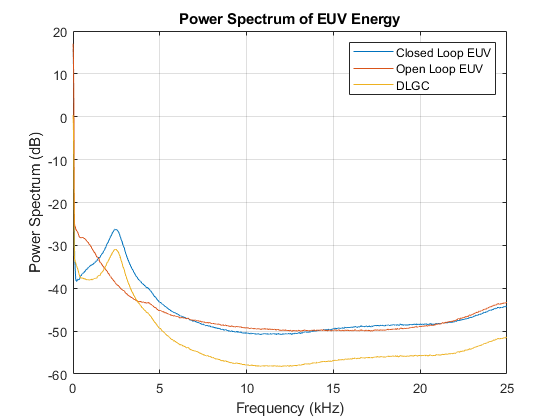

figure;
pspectrum(logsout.Ecl(logsout.enab == 1),50e3); hold on;
pspectrum(logsout.Eol(logsout.enab == 1),50e3);
pspectrum(logsout.dlgc(logsout.enab == 1),50e3);
title('Power Spectrum of EUV Energy');
legend('Closed Loop EUV','Open Loop EUV','DLGC');

## Internal and External Energy

Extract data arrays for EUV = ON (enab = 1) portions of the data. Do this for both open loop and closed loop energy for scanner/reticle energy and internal source energy.

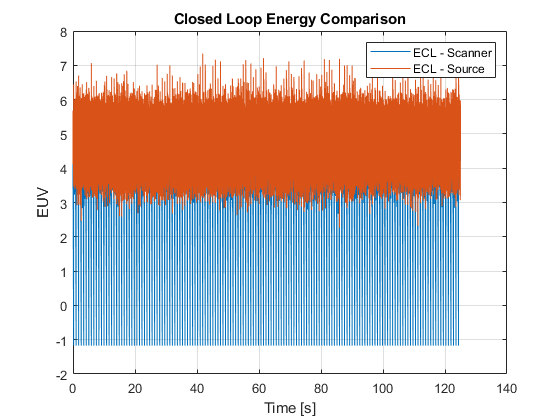

t = logsout.T_Ecl(enab == 1);
Eol_Scanner = logsout.Eol(enab == 1);
Eol_Source = logsout.Eol_Source(enab == 1);
Ecl_Source = logsout.EUV_Internal(enab == 1);
Ecl_Scanner = logsout.Ecl_delay(enab == 1);

figure;
plot(t,Ecl_Scanner); hold on; grid on;
plot(t,Ecl_Source); xlabel('Time [s]');
ylabel('EUV'); legend('ECL - Scanner','ECL - Source');
title('Closed Loop Energy Comparison')

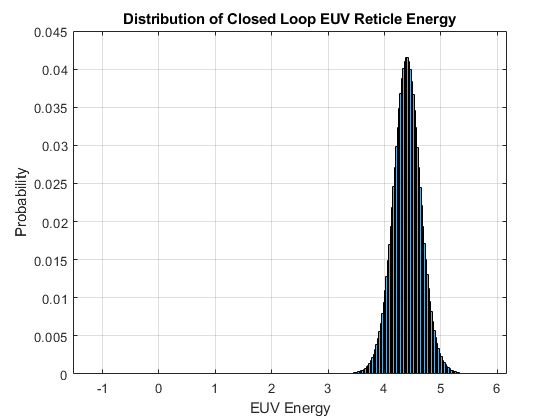


figure;
histogram(Ecl_Scanner,'Normalization','probability','BinWidth',0.025);
xlabel('EUV Energy'); ylabel('Probability');
title('Distribution of Closed Loop EUV Reticle Energy'); grid on;

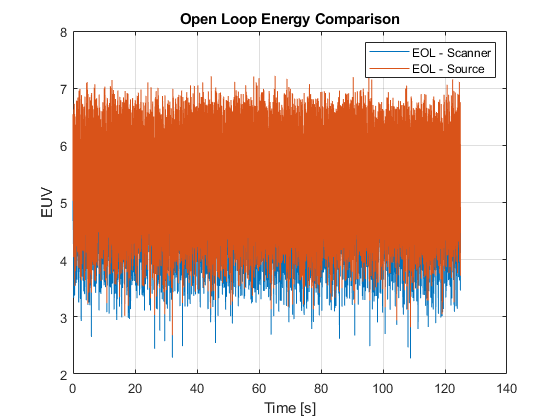


figure;
plot(t,Eol_Scanner); hold on; grid on;
plot(t,Eol_Source); xlabel('Time [s]');
ylabel('EUV'); legend('EOL - Scanner','EOL - Source');
title('Open Loop Energy Comparison');

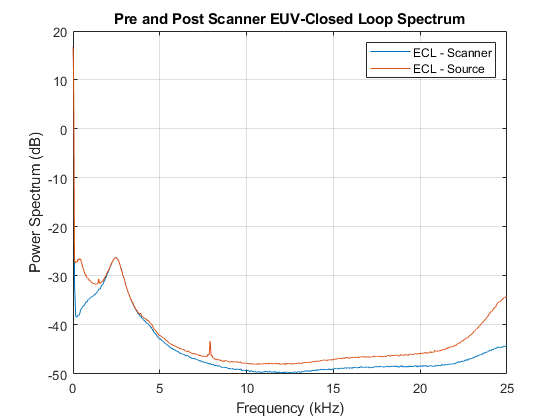

figure;
pspectrum(Ecl_Scanner,50e3); hold on;
pspectrum(Ecl_Source,50e3);
legend('ECL - Scanner','ECL - Source');
title('Pre and Post Scanner EUV-Closed Loop Spectrum')